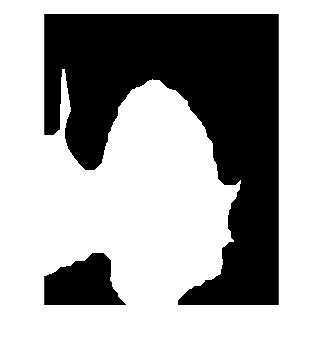

clear
% Read img file
img = imread("../db/DB0/db0_1.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes) & face_mask;

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 400

y = 232


[indexX,indexY] = eye_index(eye_mask)

indexX =     66    46    99    50   152   170   246   276   287   344   347


indexY =    425   494   313   196   487   280   347   243   276   300   450


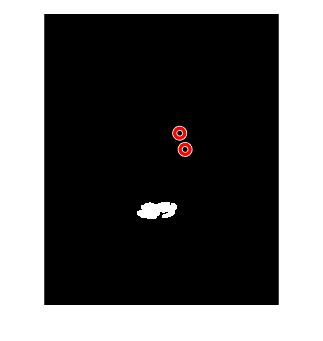

mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2] = findEyePair(indexX,indexY,mouth_center);